# Sesión 6: Métodos numéricos para valores propios

## Teoría y aplicaciones

### Álgebra Lineal

A=[4/5 -3/5 0;3/5 4/5 0;1 2 2]

A =     0.8000   -0.6000         0
    0.6000    0.8000         0
    1.0000    2.0000    2.0000


% Analíticamente
syms t
pL=det(A-t*eye(size(A)))

$$pL = -t^{3}+\frac{18\,t^{2}}{5}-\frac{21\,t}{5}+2$$

solve(pL==0)

$$ans = \left(\begin{array}{c} 2\\ \frac{4}{5}-\frac{3}{5}\,\mathrm{i}\\ \frac{4}{5}+\frac{3}{5}\,\mathrm{i} \end{array}\right)$$

% Numéricamente
[V,D]=eig(A);
L=diag(D)

L =    2.0000 + 0.0000i
   0.8000 + 0.6000i
   0.8000 - 0.6000i


disp(V)

   0.0000 + 0.0000i  -0.3660 - 0.2745i  -0.3660 + 0.2745i
   0.0000 + 0.0000i  -0.2745 + 0.3660i  -0.2745 - 0.3660i
   1.0000 + 0.0000i   0.7625 + 0.0000i   0.7625 + 0.0000i



- Un valor propio real

L1=L(1)

L1 = 2

V1=V(:,1)

V1 =      0
     0
     1


- Dos valores propios complejos conjugados

%L2=L(2)
V2=V(:,2)

V2 =   -0.3660 - 0.2745i
  -0.2745 + 0.3660i
   0.7625 + 0.0000i


%L3=L(3)
V3=V(:,3)

V3 =   -0.3660 + 0.2745i
  -0.2745 - 0.3660i
   0.7625 + 0.0000i


- Matrices simétricas: siempre tienen valores propios reales

B=A'+A

B =     1.6000         0    1.0000
         0    1.6000    2.0000
    1.0000    2.0000    4.0000


eig(B)

ans =     0.2623
    1.6000
    5.3377


### Page Rank

%Resolviendo problemas de valores y vectores propios
%para el vector de clasificacion r
clc
A=[0 1 0 1 1;0 0 1 1 1 ; 1 0 0 1 0;0 0 0 0 1;0 0 1 0 0]

A =      0     1     0     1     1
     0     0     1     1     1
     1     0     0     1     0
     0     0     0     0     1
     0     0     1     0     0


[Q,D]=eig(A);
%El primer valor es el unico real, ese es el que necesitamos
evals=diag(D);
vp1=evals(1)

vp1 = 1.6593

%Encontramos la constante de proporcionalidad alpha
alpha=1/vp1

alpha = 0.6027

%Encontramos el vector r como vector propio correspondiente al
%primer valor propio
r=Q(:,1)

r =     0.6057
    0.5537
    0.4673
    0.1697
    0.2816


%Normalizando el vector de clasificacion
r=r ./ sum(r)

r =     0.2915
    0.2664
    0.2249
    0.0817
    0.1355


- Valor propio dominante

abs(evals)

ans =     1.6593
    1.3149
    1.3149
    0.5904
    0.5904


### Círculos de Gershgorin

Cada valor propio $\lambda$ se encuentra en al menos un círculo de Gershgorin:

            $|\lambda - A_{ii}| \le \sum_{j\neq i} |A_{ij}|$  para algún $i=1,2,\dots,n$

clf
A=[3 2 4;2 0 2;4 2 3]

A =      3     2     4
     2     0     2
     4     2     3


disp('Circulos de gershgorin')

Circulos de gershgorin


fig=gershgorin(A);
[V,D]=eig(A);
L=diag(D)

L =    -1.0000
   -1.0000
    8.0000


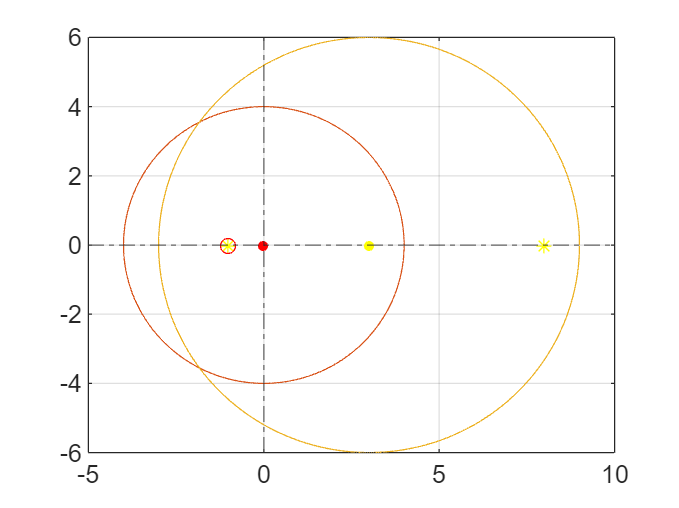

plot(A(1,1),0,'y.','MarkerSize',12); plot(L(1),0,'y*')
plot(A(2,2),0,'r.','MarkerSize',12); plot(L(2),0,'ro')
plot(A(3,3),0,'y.','MarkerSize',12); plot(L(3),0,'y*')
xline(0,'-.'); yline(0,'-.');
hold off

## Aproximación de valores propios

### Metodo de potencia

- Valor propio dominante

A=[3 2 4;2 0 2;4 2 3];
x0=ones(size(A,1),1);
Maxiter=5;
[z]=potencia(A,x0,Maxiter);
lambda1=z(end,end)

lambda1 = 8.0002

v1=z(end,1:end-1)

v1 =     1.0000    0.5000    1.0000


### QR para valores propios

% Descomposición/factorización QR
[Q R]=gs_c(A);
Q'*Q % ortogonalidad

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000         0
    0.0000         0    1.0000


R    % triangular superior

R =     1.4142    1.4142    1.4142
         0    1.7321    1.1547
         0         0    0.8165


Q*R-A  % QR=A

ans =      0     0     0
     0     0     0
     0     0     0


**Algoritmo:**

Inicialmente $\left\{
\begin{array}{c}
A=Q_1R_1 \\
A_1=R_1Q_1
\end{array}
\right.
$ 

Luego $\left\{
\begin{array}{c}
A_{k}=Q_{k+1}R_{k+1} \\ 
A_{k+1}=R_{k+1}Q_{k+1}
\end{array}
\right.$ para $k=1,2,\dots$

La sucesión de matrices $A_1,A_2,\dots \quad \to \quad T$ matriz triangular por bloques

***Los bloques en la diagonal de*** $T$ ***permiten hallar los valores propios de*** $A$

- Caso real

A=[1 -1 4;3 2 -1;2 1 -1]; %ingresamos A
L=eig(A) %calculamos los valores propios usando eig

L =     3.0000
   -2.0000
    1.0000


A1=A;
iter=500; %efectuamos 500 iteraciones
for i=1:iter
 [Q1, R1]=gs_c(A1); %la funcion gs_c factoriza QR usando G-S
 A1=R1*Q1;
end
A1

A1 =     3.0000    2.6726   -0.4364
   -0.0000   -2.0000   -4.0825
    0.0000    0.0000    1.0000


- Caso complejo

A=[4/5 -3/5 0; 3/5 4/5 0;1 2 2]; %ingresamos A
L=eig(A) %calculamos los valores propios usando eig

L =    2.0000 + 0.0000i
   0.8000 + 0.6000i
   0.8000 - 0.6000i


A1=A;
iter=500; %efectuamos 500 iteraciones
for i=1:iter
 [Q1, R1]=gs_c(A1); %la funcion gs_c factoriza QR usando G-S
 A1=R1*Q1;
end
A1

A1 =     2.0000   -1.6717   -1.4851
    0.0000    0.8000   -0.6000
    0.0000    0.6000    0.8000


A1(1,1)

ans = 2.0000

B=A1(2:3,2:3) % valores propios complejos

B =     0.8000   -0.6000
    0.6000    0.8000


eig(B)

ans =    0.8000 + 0.6000i
   0.8000 - 0.6000i


Funciones de usuario

function [Q R]=gs_c(A)
 [m,n]=size(A);
 Q=zeros(m,n);
 R=zeros(n);
 for j=1:n
 R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
 temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
 R(j,j)=norm(temp);
 Q(:,j)=temp/R(j,j);
 end
end

function [z]=potencia(A,x0,Maxiter)
 z=[x0' 1];
 for k=1:Maxiter
 y1=A*x0;
 [maxi,pos]=max(abs(y1));
 u=y1(pos); % valor propio
 x1=y1/u; %vector propio normalizado
 z=[z;x1' u];
 x0=x1;
 end
end

function [fig]=gershgorin(A)
[m,n]=size(A);
if m~=n
    error('A no es cuadrada')
end
for i=1:n
%(h;k) centro de la circunferencia
h=A(i,i);
k=0;
r=sum(abs(A(i,:)))-abs(A(i,i));
theta=[0:0.01:2*pi];
xx=r*cos(theta)+h;
yy=r*sin(theta)+k;
fig=figure(1);
plot(xx,yy)
hold on
end
grid on
end